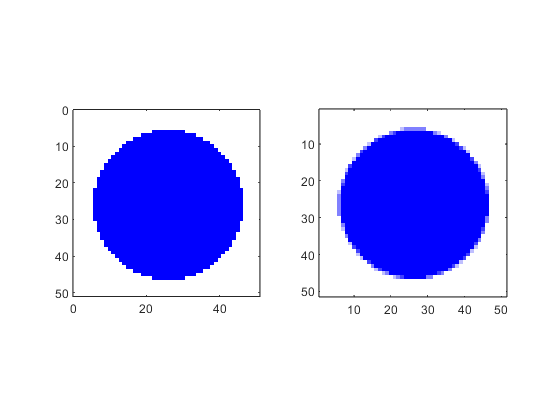

clear

% Raster parameters
Nx = 51;
Ny = 51;
img = uint8(255 * ones(Ny, Nx, 3));
ss = 255 * ones(2 * Ny, 2 * Nx, 3);

% Circle parameters
cx = round(Nx / 2);
cy = round(Ny / 2);
r = 20;
blue = [0, 0, 255];

% Draw filled circle
img = drawcircle(img, cx, cy, r, blue);
img = floodfill(img, cx, cy, [255,255,255], blue);

% Apply antialiasing
ss = drawcircle(ss, 2*cx, 2*cy, 2*r, blue);
ss = floodfill(ss, 2*cx, 2*cy, [255,255,255], blue);

i = 1 : Ny;
j = 1 : Nx;
img2(i, j, :) = uint8((ss(2*i-1,2*j-1,:) + ss(2*i,2*j-1,:) + ss(2*i-1,2*j,:) + ss(2*i,2*j,:)) / 4);

% Plot raster
subplot(1, 2, 1)
image(img)
axis equal
axis([0, Nx, 0, Ny])

subplot(1, 2, 2)
image(img2)
axis equal
axis([0, Nx, 0, Ny])
exportgraphics(gcf,'../images/antialiasing_example.png','Resolution',300) 

function R = drawcircle(R, cx, cy, r, colour)

D = 5 - 4 * r;
x = r;
y = 0;
while y <= x
    R(cy+y, cx-x, :) = colour;
    R(cy-y, cx+x, :) = colour;
    R(cy-y, cx-x, :) = colour;
    R(cy+x, cx+y, :) = colour;
    R(cy+x, cx-y, :) = colour;
    R(cy-x, cx+y, :) = colour;
    R(cy-x, cx-y, :) = colour;
    R(cy+y, cx+x, :) = colour;

    if D > 0
        D = D - 8 * x + 8 * y + 20;
        x = x - 1;
    else
        D = D + 8 * y + 12;
    end
    y = y + 1;
end

end